This example demonstrates the quantum teleportation circuit as described in figure 1.13 in the Nielsen and Chuang text book.

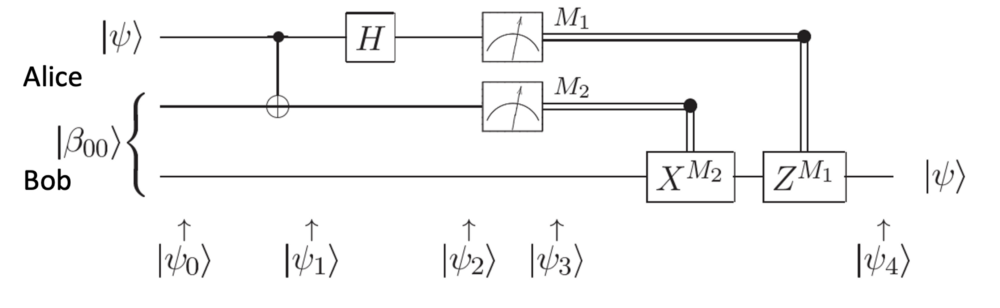

We now create an entangled resource by applying a haddamard gate and a CNOT gate on the zero state of a two qubit register

entangledRegister = qregister(2,0);
entangledRegister = hGate(entangledRegister,0);
entangledRegister = cnotGate(entangledRegister,0,1);

Now we create a random ket (note: qregister handles the normalization)

randVec = [(rand() + 1i*rand()); (rand() +1i*rand())];
initialQubit = qregister(randVec);

% store the state for later analysis
initialState = initialQubit.getState();

Now we combine the register and our state is the same as the start state at the start of the circuit

register = initialQubit.concatenateRegiser(entangledRegister);

As the circuit instructs we apply the Cnot and hadamard gates to the appropriate qubits

register = cnotGate(register,0,1);
register = hGate(register,0);

Next we perform destructive measurments on the register.  By passing in true we spcify that the qubit measured should be thrown out and the hilbert space size should be reduced.

[finalQubit, measurmements] = measure_sequence(register,[0,1],true);

measurements holds the array values of the results and finalQubit hods a 1-qubit register.

As the circuit displays we have to selectively apply gates

if measurmements(2) == 1
    finalQubit = xGate(finalQubit,0);
end
if measurmements(1) == 1
    finalQubit = zGate(finalQubit,0);
end

The final state is

finalState = finalQubit.getState();

Now we check that the states are approximately equal

diffState = (finalQubit.getState() - initialState);
% The norm difference
normDiff = transpose(conj(diffState)) * diffState

normDiff = 0

normDiff may be some small number due to floating point operations.